Code for 2b

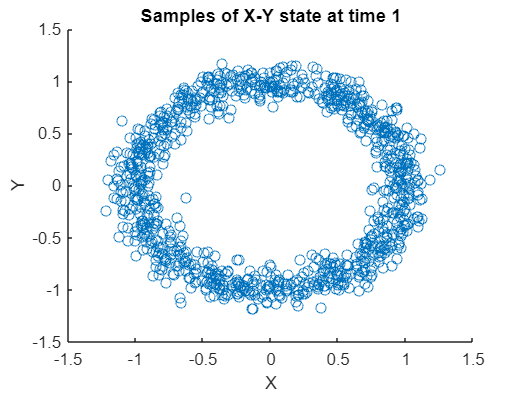

% Given mean and covariance
mean_initial = [0; 0; 0];
covariance_initial = [0.01 0 0; 0 0.01 0; 0 0 10000];

% Generate samples from the Gaussian distribution
initial_samples = mvnrnd(mean_initial, covariance_initial, 1000);
% Given time step
delta_t = 1; % Assume distance covered in one time step is 1

% Initialize array to store propagated states
propagated_states = zeros(1000, 3);

% Propagate each sample according to the motion equation
for i = 1:1000
    x_k = initial_samples(i, 1);
    y_k = initial_samples(i, 2);
    theta_k = initial_samples(i, 3);
    
    x_k1 = x_k + delta_t * cos(theta_k);
    y_k1 = y_k + delta_t * sin(theta_k);
    
    propagated_states(i, :) = [x_k1, y_k1, theta_k];
end
% Plot x-y state samples at time 1
scatter(propagated_states(:, 1), propagated_states(:, 2));
xlabel('X');
ylabel('Y');
title('Samples of X-Y state at time 1');

Code for 2c

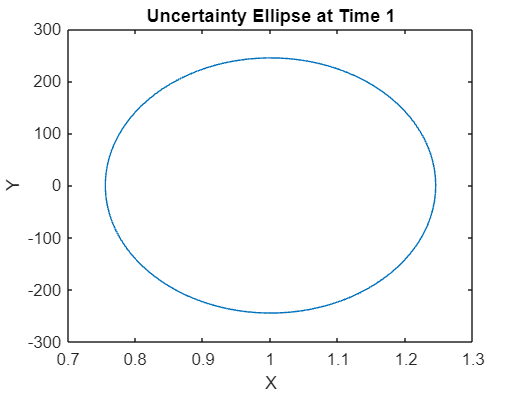

% Given mean and covariance
mean_bar_1 = [1; 0; 0]; % Provided mean at time 1
covariance_bar_1 = [0.01 0 0; 0 10000 10000; 0 10000 10000]; % Provided covariance at time 1

% Define the confidence level (e.g., 0.95 for 95% confidence)
confidence_level = 0.95;

% Plot the uncertainty ellipse
plotErrorEllipse(mean_bar_1(1:2), covariance_bar_1(1:2, 1:2), confidence_level);
xlabel('X');
ylabel('Y');
title('Uncertainty Ellipse at Time 1');